r = 3;
x0 = 4;
y0 = 5;
dev = .05;
t = linspace(0,deg2rad(60),60)';
npts = length(t);
x = cos(t)*r+x0+randn(npts,1)*dev;
y = sin(t)*r+y0+randn(npts,1)*dev;
[cent_found,r_found] = findCenter(x,y)

w =    -9.8624
  -11.0923
   51.0650


cent_found =     4.9312    5.5461


r_found = 2.0029

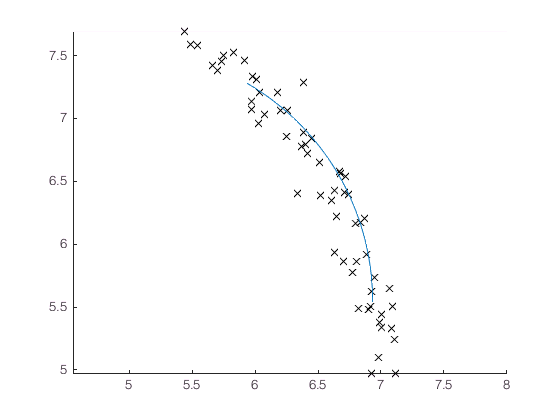

figure
clf
hold on
plot(x,y,'kx')
plot(cos(t)*r_found+cent_found(1),sin(t)*r_found+cent_found(2))
axis equal
hold off

function [cent, r] = findCenter(x ,y)
    nPoints = length(x);
    A = [x y ones(nPoints,1)];
    b = -x.^2-y.^2;
    w = A\b
    cent = [-w(1)/2 -w(2)/2];
    r = sqrt(cent(1)^2 + cent(2)^2 -w(3));
%     nPoints = length(x);
%     bestCost = Inf;
%     bestCent = [0;0];
%     bestR = 0;
%     XY = [x y];
%     for succ = 1:nTries
%         i=0;
%         j=0;
%         k=0;
%         while(i==j || i==k || j==k)
%             i = randi(nPoints);
%             j = randi(nPoints);
%             k = randi(nPoints);
%         end
%         a = [x(i);y(i)];
%         b = [x(j);y(j)];
%         c = [x(k);y(k)];
%         
%         abCent = mean([a b],2);
%         acCent = mean([a c],2);
%         ab = b-a;
%         ac = c-a;
%         nab = [-ab(2);ab(1)];
%         nac = [-ac(2);ac(1)];
%         
%         ut = linsolve([nab,-nac],acCent-abCent);
%         
%         cent = abCent + ut(1)*nab;
%         A = XY - cent';
%         %r = mean(sqrt(diag(A*A')));
%         r = norm(a-cent);
%         
% %         abc = [a b c];
% %         cents = [abCent, acCent];
%         
%                 
%         
%         cost = sum(circleCost(x, y, cent, r));
%         
% %         hold on
% %         plot(x,y,'ks');
% %         plot(abc(1,:), abc(2,:), 'go');
% %         plot(cents(1,:), cents(2,:), 'ro');
% %         quiver(abCent(1), abCent(2), nab(1), nab(2));
% %         quiver(acCent(1), acCent(2), nac(1), nac(2));
% %         plot(cent(1),cent(2),'m*');
% %         t = linspace(0,2*pi);
% %         plot(cos(t)*r+cent(1), sin(t)*r+cent(2));
% %         axis equal
% %         hold off
% %         figure
%         if(cost < bestCost)
%             bestCost = cost;
%             bestCent = cent;
%             bestR = r;
%         end
%     end
end

